# **Performance Testing of Air Source Heat Pump (ASHP) System**

## 0. Setup

Code initiation

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

Load and Organize the data

clear data temp

data(1).d = readmatrix('Data 33F.xlsx', 'NumHeaderLines', 1);
data(2).d = readmatrix('Data 36F.xlsx', 'NumHeaderLines', 1);
data(3).d = readmatrix('Data 37F.xlsx', 'NumHeaderLines', 1);
data(4).d = readmatrix('Data 38F.xlsx', 'NumHeaderLines', 1);
data(5).d = readmatrix('Data 39F.xlsx', 'NumHeaderLines', 1);
data(6).d = readmatrix('Data 40F.xlsx', 'NumHeaderLines', 1);
data(7).d = readmatrix('Data 41F.xlsx', 'NumHeaderLines', 1);

Conversions:

% Farhenheit to Celsius
%
% psi to MPa
mpa = 145;

Evaporator Outlet Temp/Compressor Inlet Temp:

for i = 1 : size(data,2)
    hp(i).evapoutcompin_temp = (mean(data(i).d(:,1)) - 32) * (5/9);
end

Condenser Inlet Temp

for i = 1 : size(data,2)
    hp(i).condin_temp = (mean(data(i).d(:,2)) - 32) * (5/9);
end

Room Temp

for i = 1 : size(data,2)
    hp(i).room_temp = (mean(data(i).d(:,3)) - 32) * (5/9);
end

Outdoor Temp

for i = 1 : size(data,2)
    hp(i).out_temp = (mean(data(i).d(:,4)) - 32) * (5/9);
end

Condenser Inlet Pressure

for i = 1 : size(data,2)
    hp(i).condin_pres = mean(data(i).d(:,5))/mpa;
end

Evaporator Exit Air Temp

for i = 1 : size(data,2)
    hp(i).evapexa_temp = (mean(data(i).d(:,6)) - 32) * (5/9);
end

Refrigerant Flow Rate (GPM)

for i = 1 : size(data,2)
    hp(i).rflowrate = mean(data(i).d(:,7));
end

Condenser Outlet Pressure

for i = 1 : size(data,2)
    hp(i).condout_temp = mean(data(i).d(:,8))/mpa;
end

Condenser Outlet Temp

for i = 1 : size(data,2)
    hp(i).condin_temp = (mean(data(i).d(:,9)) - 32) * (5/9);
end

## 1. Calculate Heating Capacity

Heating Capacity:

## 
$$Q_h = \dot{m}_r \left( h_{2,r} - h_{3
,r} \right)$$


Where,

- $h_{2,r}$ = Refrigerant Enthalpy at Compressor Outlet/Condensor Inlet

- $h_{3,r}$ = Refrigerant Enthalpy at Condenser Outlet

- $\dot{m}_r$ = Refrigerant flowrate

Enthalpy is found from the following P-h diagram of R410A refrigerant (example for 33F outdoor temp):

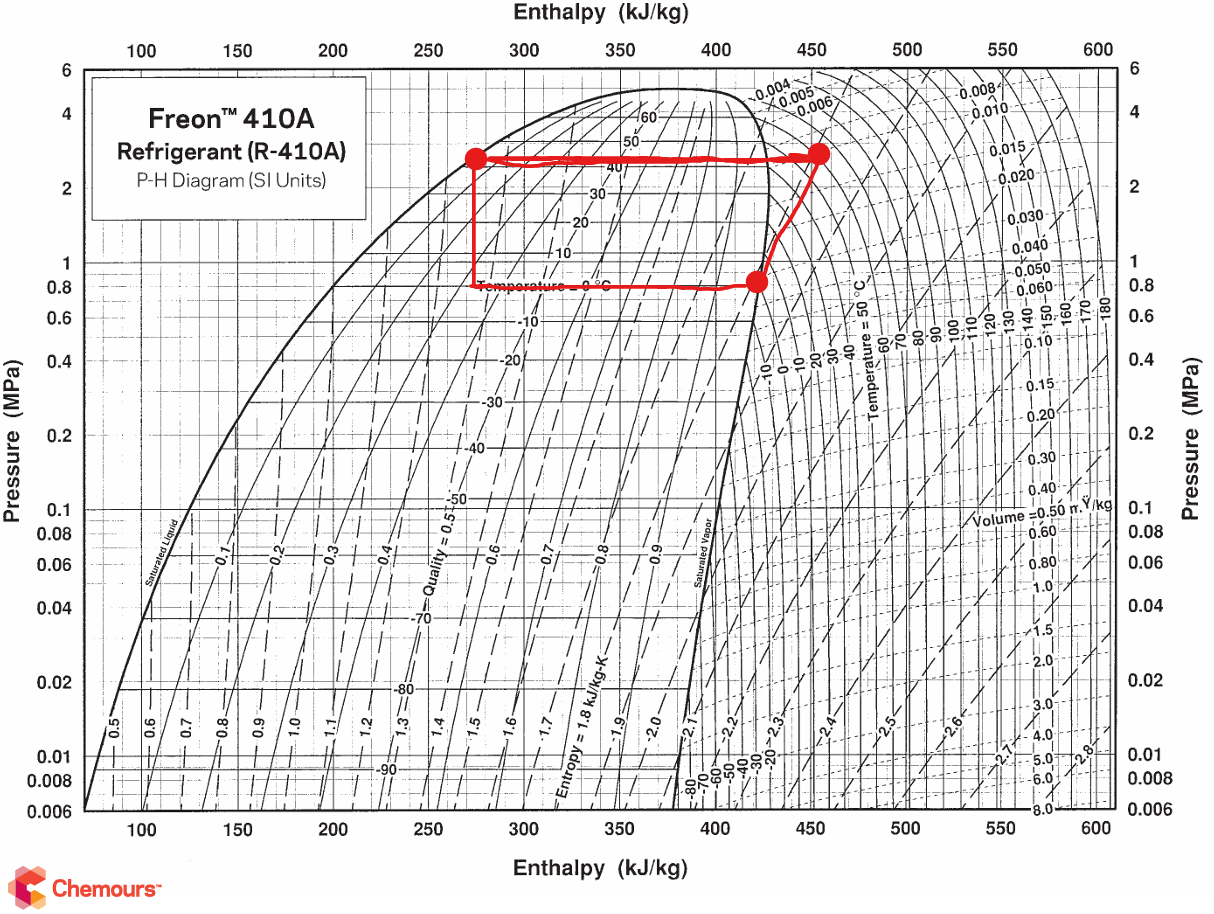

## 2.  Calculate Coefficient Of Performance 

Coefficient of Performance (COP):

## 
$$COP = \frac{\dot{m}_r \left( h_{2,r} - h_{3
,r} \right)}{W_{c,in}}$$


Where,

- $W_{c,in}$ = Compressor Power Input

## 3. Plot Q vs. COP

Compute uncertainty of the temperature measurement based on 60 samples and add error bars to the $T_{ss}(x)$ plot.

## 5. All MATLAB Calculations

In Appendix B, show the sample of all calculations done in MATLAB.

%{

Just export this livescript as  matlab script or word document

%}